direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

shape_step = 0.05;
% shape is alpha; shapechange is alpha dot
a = s.grid_range(1):shape_step:s.grid_range(2);
adot = -0.5:0.01:0.5;

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, a, adot);

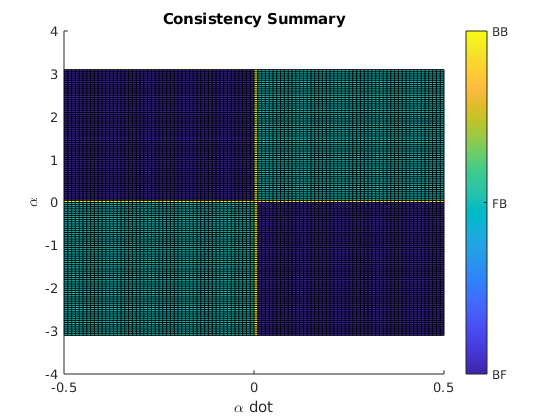

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot, a, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

% get a body velocity
i = 40; j = 30;
bvel = apply_piecewise_system(s, system_map, a, adot, i, j);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot(j)];
end

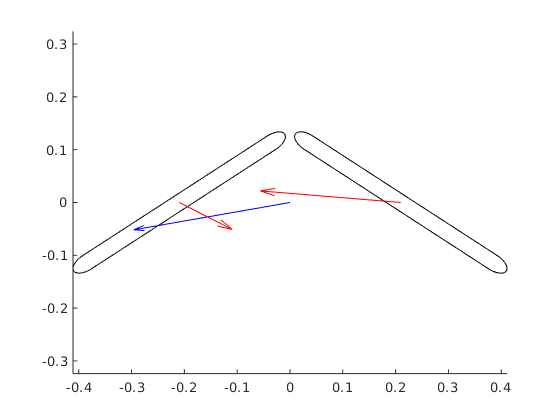

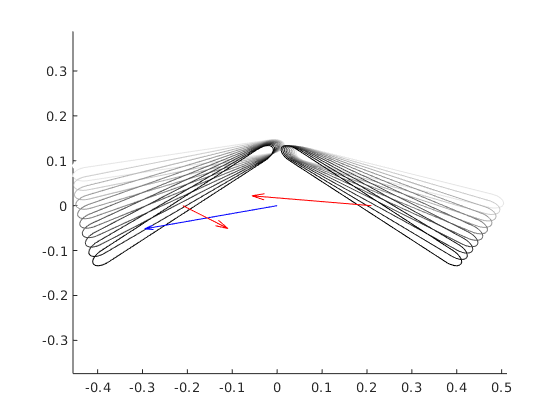

% plot
velocity_diagram(s, lvel, bvel, a(i), adot(j), 0, 0);